# Fit a Line to Data

This code loads flow data. 

knobSetting=[0 1 2 3 4 5]'

knobSetting =      0
     1
     2
     3
     4
     5


flowRate=[0 2.3 4.2 7.2 8.4 11.9]'

flowRate =          0
    2.3000
    4.2000
    7.2000
    8.4000
   11.9000


## Task 1

The variables `knobSetting` and `flowRate` are column vectors containing the data from the table below: 

The knob setting is the independent variable, and the flow rate is the dependent variable. 

Recall that you can perform linear regression with the `fit` function by using `"poly1"` as the third input: 

`fitResult` `=` `fit``(``x``,``y``,``"poly1"``)`

Task

Perform linear regression on the variables `knobSetting` and `flowRate` using the `fit` function. Name the output variable `flowfit`. 

Leave off the semicolon to display the output.

flowfit=fit(knobSetting,flowRate,"poly1")

flowfit =      Linear model Poly1:
     flowfit(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       2.309  (1.976, 2.642)
       p2 =     -0.1048  (-1.113, 0.9035)

## Task 2

The slope is stored as `p1` in `flowfit`.  

You can extract the coefficients of the model using dot notation. 

`flowfit.``CoefficientName`

Task

Extract the slope of the linear model to a variable named `slope`. 

slope=flowfit.p1

slope = 2.3086

## Task 3

The intercept is stored as `p2` in `flowfit`.  

Task

Extract the intercept of the linear model to a variable named `intercept`. 

intercept=flowfit.p2

intercept = -0.1048

## Task 4

Now you now know that the equation of the best fit line is 

y=2.3x−0.1.

You can plot this line, along with your data, using the `plot` function with three inputs:

`plot``(``modelName``,``xData``,``yData``)`

Task

Plot the linear model and flow rate data using the `plot` function.

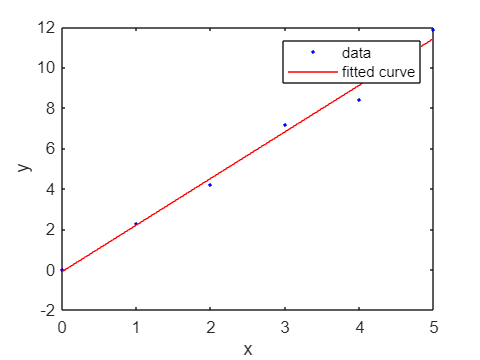

plot(flowfit,knobSetting,flowRate)